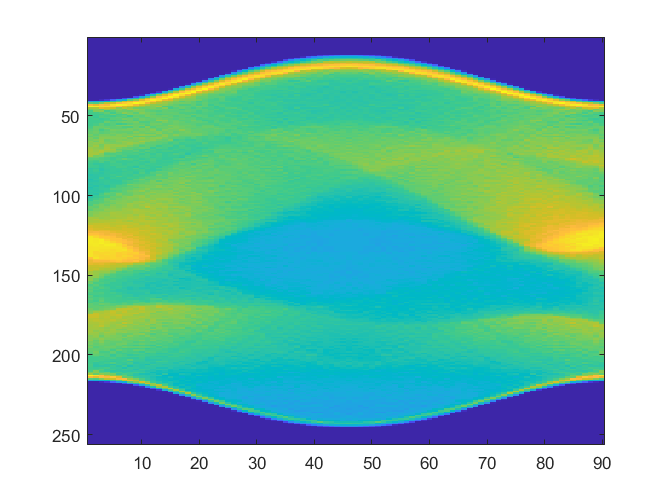

angle =      0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98


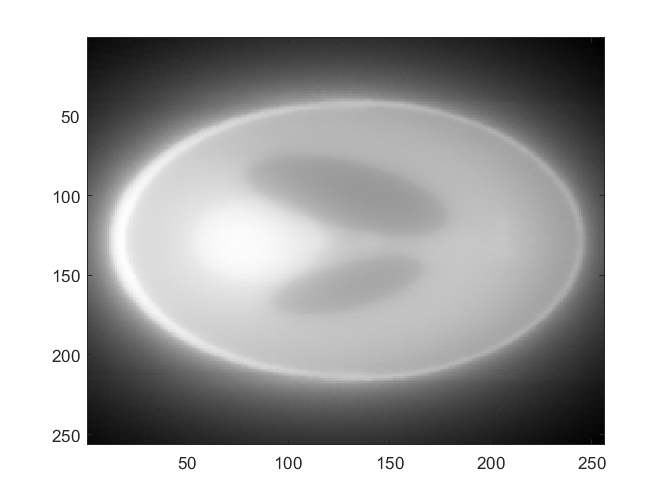

clear
clf

p = phantom(256,256);

figure(1), imagesc(p), colormap('gray')
title('Shepp-logan Phantom')
p0s = sum(p);
figure(2),subplot(211), plot(p0s)
pr = imrotate(p,45,'crop');
p45s = sum(pr);
figure(2),subplot(212), plot(p45s)
figure(3), imagesc(pr), colormap('gray')

numAng = 180;
stepAng = 180/numAng;
ang = [0:stepAng:180-stepAng]

for i=1:numAng
    pr = imrotate(p,ang(i),'crop');
    R(:,i) = sum(pr);
    figure(4), imagesc(R), colormap('gray')
    xlabel('Theta')
    ylabel('Number of Detector')
    title('Sinogram')
    %pause(0.5)
end


% Back Projection
f = zeros(256,256);
for theta = 1:numAng
    for i = 1:256
        for j = 1:256
            s = floor((i-128)*cos(ang(theta))+(j-128)*sin(ang(theta))+128);
            if (s>0 && s<256)
               f(i,j) = f(i,j) + R(s,theta);
            end
        end
    end
    figure(5), imagesc(f), colormap('gray');
    pause(0.5)
end